To construct data for our emulation examples, we solve a viscous Burgers' equation with an additional cubic reaction term


$$\frac{\partial u}{\partial t} + \frac{\partial u^2}{\partial x} = \nu \frac{\partial^2 u}{\partial x^2}  + r u (a-u)(u-b)

$$


with initial condition $u(x,0)=abs(sin(2 \pi k x)
$

and periodic boundary conditions $u(0,t)=u(1,t)$

Let's set $a=1$and use as parameters for emulation some combination of $b, k, r$.

Here we will work with the two inputs $k,r$ and fix $b.$

The numerical scheme is a mid-time predictor-corrector, using a Davis Scheme for the Burgers' nonlinearity, and explicit differencing for the viscous term and the reaction term. The overall scheme is formally second-order accurate.

%%function advectionreaction
% 1D
% du/dt + (1/2) d(u^2)/dx = nu d^2u/dx^2 + u(a-u)(u-b)
% 
%
% Davis scheme
% periodic boundary conditions.
% initial sinusoid of varying spatial frequency
%  
% Parameters
n = 101;                  % grid size
dx = 1.0/n;  
a=1.0;  nu=0.01; 
%%B=[0.25,0.5,0.75]; KK=[0.5,1.0,1.5]; RR=[1.0,2.0];
% for 2inputsonly
B=[0.75]; KK=[0.5,1.0,1.5,2.0]; RR=[0.5,1.0,2.0];
count=0;
for i=1:length(B)
    for j=1:length(KK)
        for h=1:length(RR)
            count=count+1;
            phere=[B(i), KK(j), RR(h)];
            param(count,:,:,:)=phere;
        end
    end
end
paramlength=count;
% size, plot interval
x=linspace(0,1,n);
nplotstep = 20;          

% Outer loop
   uwavex=zeros(paramlength,n);
   ntrial=paramlength;
% loop over parameter inputs
   for ploop = 1:ntrial
       k=param(ploop,2);
       b=param(ploop,1);
       react=param(ploop,3);
   
   u = zeros (n,1);    
   us =zeros(n,1);    
   
   du=zeros(n,1); 
   uleft=zeros(n,1); 
   uright=zeros(n,1);
   for i=1:n
      u(i)=abs(sin(2*pi*k*x(i)));
   end
  
%  timestep  explicit for viscous term being conservative
   maxspeed=max(1,max(a,b));
   dt=0.25*dx*dx/nu; dt2=0.5*dt;
   time=0.0; nstep=0;
 
   % for each parameter set, a time loop
   maximumtime=0.5; 
    while(time <maximumtime)
    nstep = nstep + 1;
    timep = time+dt; 
    if (timep > maximumtime)
        dt=maximumtime-time;
        timep=time+dt;
    end
    time=timep;
    
       %slopes
       for i=2:n-1
           dup=u(i+1)-u(i);
           dum=u(i)-u(i-1);
           du(i)=0.5*(sign(dup)+sign(dum))*...
               min([2*abs(dup),2*abs(dum),0.5*(abs(dup+dum))]);
       end
       du(1) = du(n-1);     
       du(n) = du(2); 
       % mid-time predictor

       for i = 2:n-1
       us (i) = u(i)-(dt2/(dx))*u(i)*du(i) ...
           + nu*(dt2/(dx*dx))*(u(i+1)-2.0*u(i)+u(i-1)) ...
           + react*(dt2)*(u(i)*(a-u(i))*(u(i)-b));
       end
       % Periodic boundary conditions 
       us(1) = us(n-1);     
       us(n) = us(2); 
       
       % Left and Right Riemann states...note indexing is based on cell
       % center
       for i=1:n
           uleft(i)=u(i) - 0.5*dx*du(i);
           uright(i)=u(i) + 0.5*dx*du(i);
       end
       speed=ones(n,1);
       for i=1:n-1
           speed(i)=max(abs(us(i)),abs(u(i+1)));
       end
       speed(n)=speed(1);
 
       % Conservative update   Rusanov flux
       for i = 2:n-1
       fluxp=0.5*(uright(i)^2 + uleft(i+1)^2)/2 ...
           -(speed(i)/2)*(uleft(i+1)-uright(i));
       fluxm=0.5*(uright(i-1)^2 + uleft(i)^2)/2 ...
           -(speed(i-1)/2)*(uleft(i)-uright(i-1));
       u(i) = u(i)-(dt/dx)*(fluxp-fluxm) ...
            + nu*(dt2/(dx*dx))*(us(i+1)-2.0*us(i)+us(i-1)) ...
            + react*(dt)*(us(i)*(a-us(i))*(us(i)-b));
       end
       % Periodic boundary conditions 
       u(1) = u(n-1);     
       u(n) = u(2);

       % Update plot
%% If you want to plot, uncomment the plot, axis, and Mov lines with
%%  a %%
 %      if mod (nstep,nplotstep) == 0
   %       C = abs (U (i));  % Color shows momemtum
   %       t = nstep*dt;
  %        tv = norm (C,'fro');
%%          plot(x,u);
%%          axis([0 1 -0.0 1]);
%%          Mov(nstep)=getframe;
%          set (ploth,'zdata',H (i));
%          set (top,'string',sprintf ('t = %6 .2f,  tv = %6 .2f',t,tv))
 %         drawnow
%      end

      
 %      if all (all (isnan (H))), break, end  % Unstable, restart
 %  end

%close (gcf)

   end
%   time   check all loops run to limit

%   set up output files for each ploop
   ut(:)=transpose(u(:));
   invwaveu(ploop,:)=ut(:);
   integrand1=(u.^2);
   integral1(ploop,1)=sqrt(sum(integrand1*dx));

end

%movie(Mov)

%   write output files
save('advectparam.txt','param','-ascii')
save('advectu.txt','invwaveu','-ascii');
save('advectintegral.txt','integral1','-ascii')

% ------------------------------------
%end


This next code chunk generates a movie, if you want to see the waves propagate.

It is much faster to keep the call to a movie (lines 120-122) commented out.

%%function [plot,start,stop] = initgraphics (n);
% INITGRAPHICS  Initialize graphics for showing a movie
% [plot,top,start,stop] = initgraphics (n)
% returns handles to a  plot, its title, and two uicontrol toggles.

   clf
   shg
   set (gcf,'numbertitle','off','name','Acoustics')
   x = (0:n-1)/(n-1);
   ploth = plot(x,ones (n,1));
   grid off
   axis ([0 1 -1 3])
   caxis ([-1 1])
   shading faceted
   c = (1:64)'/64;
   cyan = [0*c c c];
   colormap (cyan)
  % top = title ('Click start');
   start = uicontrol ('position',[20 20 80 20],'style','toggle','string','start');
   stop = uicontrol ('position',[120 20 80 20],'style','toggle','string','stop');

%end


So this advection code generates a .txt file advectparam, containing a 3-vector of input parameter, an advectu.txt file which is the output $u(x,\cdot)$, for all x's, at each time, and a file advectintegral.txt, which calculates the integral of u at the final time, $\int u(x,t_{final}) dx$.  

Now to the business of emulation.  In matlab, the script ppgasp in the functions folder creates the emulator (for either scalar or vector output). Note: must compile the C++ files using compile_cpp(); you need to do this only once. The function ppgasp constructs the emulator. The function prediction_predict_ppgasp evaluates the prediction. 

%   function integralemulate
addpath('functions');  
%emulate velocity u in viscous Burgers-reaction advection.m
%reaction term=r*u*(1-u)*(u-b)
% params contains the b, the frequency k of IC, and a reaction rate r
% 2D param input for plotting in 2D and 3D (parameter inputs)

% datasets
intdatain=readmatrix('advectintegral.txt');
pdatain=readmatrix('advectparam.txt');
%%2D emulation only  which inputs are constant?
pdatain(:,1)=[];
intdatain(:,1:3)=[];
% size of inputs
nparams=length(pdatain(:,1));
indices=randperm(nparams);

trainset=intdatain(indices(1:nparams-1),1);
trainparam=pdatain(indices(1:nparams-1),:);
testset=intdatain(indices(nparams),:);
testparam=pdatain(indices(nparams),:);

%call PPE
       intmodel=ppgasp(trainparam,trainset);

The upper bounds of the range parameters are 59.452460 59.452460 
The initial values of range parameters are 1.189049 1.189049 
Start of the optimization 1: 
Elapsed time is 0.043810 seconds.
The number of interation is 9 
The number of function evaluation is 11 
The log marginal posterior is 46.492183 
The optimized range parameters are 2.076820 14.931490 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [11×2 double]
                output: [11×1 double]
               num_obs: 11
                     k: 1
                     p: 2
                     X: [11×1 double]
             zero_mean: 0
                     q: 1
                nugget: 0
            nugget_est: 0
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 0.6633
           kernel_type: [2×1 string]
                 alpha: [2×1 double]
           lower_bound: 1
              max_eval: 90
        initial_values: [2×3 double]
    num_initial_values: 2
       kernel_type_num: [2×1 double]
                    R0: [11×11×2 double]
                    CL: [2×1 double]
                    LB: [2×1 double]
              log_post: 46.4922


The initial values of range parameters are 0.545455 0.545455 
Start of the optimization 2: 
Elapsed time is 0.007296 seconds.
The number of interation is 9 
The number of function evaluation is 11 
The log marginal posterior is 46.492183 
The optimized range parameters are 2.076820 14.931488 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.


       predint=predict_ppgasp(intmodel,testparam);
       %predint.mean is the mean 
       intprediction=predint.mean

intprediction = 0.6871


       testset 

testset = 0.6873

       % error
       percenterr=100*(testset-intprediction)/testset  

percenterr = 0.0183

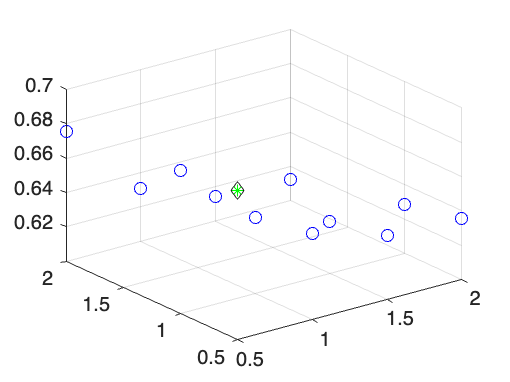

       %% a scatterplot of the original data, the training data, and the scalar output integral
       %% in 2 dimensions (the 2D input parameters)
figure
scatter3(pdatain(indices(1:nparams-1),1),pdatain(indices(1:nparams-1),2),intdatain(indices(1:nparams-1),1),'bo');
hold on
scatter3(pdatain(indices(nparams),1),pdatain(indices(nparams),2),intdatain(indices(nparams),1),'k diamond');
hold on
scatter3(pdatain(indices(nparams),1),pdatain(indices(nparams),2),intprediction,'g*');
hold on


%end

You may have to look carefully to see any discrepancy in the predicted value.

The code does calculate the error between the predicted value of the integral and the actual value calculated in the simulator.

Now to the Parallel Partial Emulator. Same structure as the scalar emulation. Note that the training data -- the u's -- are written as long row vectors. You might want to look at the example file in the ppgaps release.

%function advectemulate
addpath('functions');  
%emulate velocity u in viscous Burgers-reaction advection.m
%reaction term=r*u*(1-u)*(u-b)
% params contains the b, the frequency k of IC, and a reaction rate r
% 2D param input for plotting in 2D and 3D (parameter inputs)

% datasets
udatain=readmatrix('advectu.txt');
pdatain=readmatrix('advectparam.txt');

% size of inputs
nx=length(udatain(1,:));
nparams=length(pdatain(:,1));
%mix up input indices
indices=randperm(nparams);
%select training data a 1 test data input/output
trainset=udatain(indices(1:nparams-1),:);
%%2D emulation only  which inputs are constant?
trainparam=pdatain(indices(1:nparams-1),2:3)

trainparam =     1.0000    1.0000
    1.5000    0.5000
    1.0000    2.0000
    1.0000    0.5000
    2.0000    1.0000
    0.5000    1.0000
    2.0000    0.5000
    0.5000    2.0000
    2.0000    2.0000
    0.5000    0.5000


testset=udatain(indices(nparams),:);
testparam=pdatain(indices(nparams),2:3)

testparam =     1.5000    1.0000



%call PPE
       umodel=ppgasp(trainparam,trainset);

The upper bounds of the range parameters are 72.177060 72.177060 
The initial values of range parameters are 1.443541 1.443541 
Start of the optimization 1: 
Elapsed time is 0.017293 seconds.
The number of interation is 19 
The number of function evaluation is 26 
The log marginal posterior is 3065.425908 
The optimized range parameters are 0.500773 19.583349 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [11×2 double]
                output: [11×101 double]
               num_obs: 11
                     k: 101
                     p: 2
                     X: [11×1 double]
             zero_mean: 0
                     q: 1
                nugget: 0
            nugget_est: 0
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 0.6633
           kernel_type: [2×1 string]
                 alpha: [2×1 double]
           lower_bound: 1
              max_eval: 90
        initial_values: [2×3 double]
    num_initial_values: 2
       kernel_type_num: [2×1 double]
                    R0: [11×11×2 double]
                    CL: [2×1 double]
                    LB: [2×1 double]
              log_post: 3.0654e+03


The initial values of range parameters are 0.545455 0.545455 
Start of the optimization 2: 
Elapsed time is 0.015235 seconds.
The number of interation is 18 
The number of function evaluation is 24 
The log marginal posterior is 3065.425908 
The optimized range parameters are 0.500773 19.583354 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [11×2 double]
                output: [11×101 double]
               num_obs: 11
                     k: 101
                     p: 2
                     X: [11×1 double]
             zero_mean: 0
                     q: 1
                nugget: 0
            nugget_est: 0
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 0.6633
           kernel_type: [2×1 string]
                 alpha: [2×1 double]
           lower_bound: 1
              max_eval: 90
        initial_values: [2×3 double]
    num_initial_values: 2
       kernel_type_num: [2×1 double]
                    R0: [11×11×2 double]
                    CL: [2×1 double]
                    LB: [2×1 double]
              log_post: 3.0654e+03
              beta_hat: [2×1 double]



       predu=predict_ppgasp(umodel,testparam);
       uprediction=predu.mean;

% L2 error
       err1=(udatain(indices(nparams),:)-uprediction);
       absdiff=abs(err1.^2);
       sizeerr=sqrt(sum(absdiff*(1/nx)))

sizeerr = 5.5338e-04


% plot prediction (red) and simulator output (blue)
       figure
       plot(udatain(indices(nparams),:),'b')
       hold

Current plot held


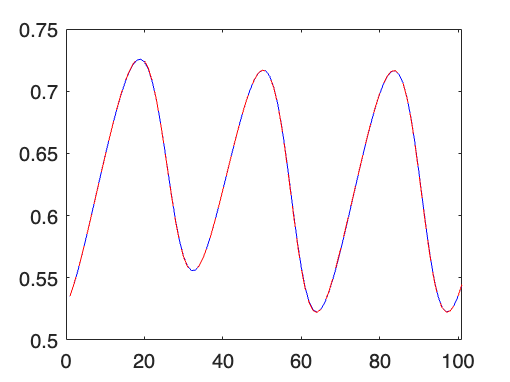

       plot(uprediction,'r--')

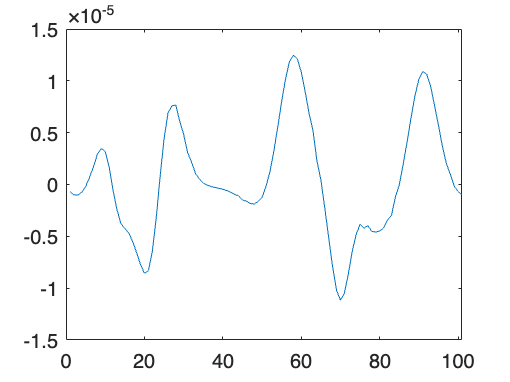

% plot error
       figure
       plot(err1*(1/nx))

%end

There is a difference between the predictor and the simulator output, but it is small for many of the parameter inputs.  If you want to push the emulator a bit more, use the 3 parameter inputs in the advection code and run this emulator script (change lines 237-239).